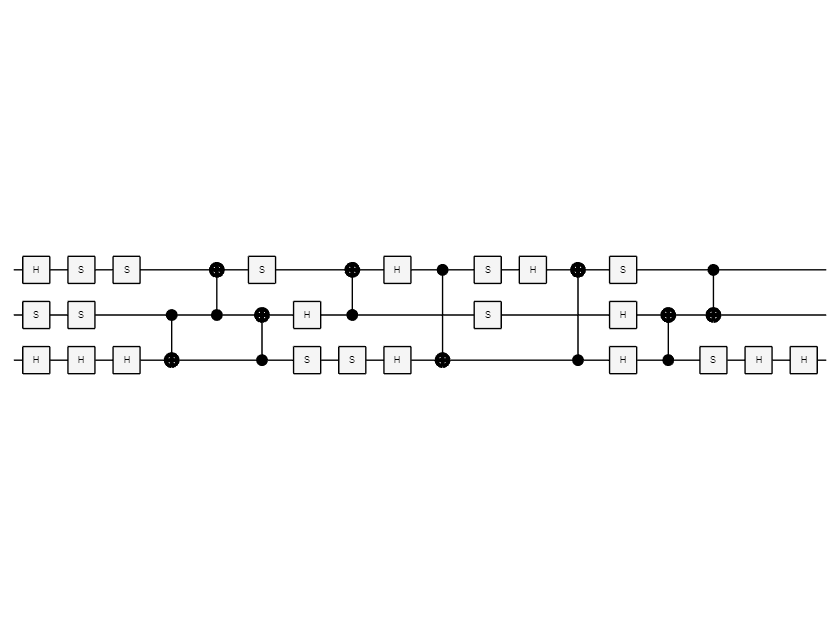

nQubits = 3;
numCliffords = 1;
p=randperm(nQubits);
% Generate a random Clifford circuit
CliffordSet = generate_unique_cliffords(nQubits, numCliffords);
cliffordEncrypt = CliffordSet{1};
%ig = initGate(1:2, "10");
swap_gates = permutationToSwapGates(p);
gates = [swap_gates; cliffordEncrypt; ];
C = quantumCircuit(gates);

plot(C);

% Apply decryption (reverse order + inverse S)
DecryptedCircuit = decrypt_clifford(CliffordSet{1}); 

  31×1 SimpleGate array with gates:

       Id   Gate   Control   Target
       1    h                3     
       2    h                3     
       3    s                3     
       4    cx     1         2     
       5    cx     3         2     
       6    h                2     
       7    h                3     
       8    s                1     
       9    cx     3         1     
       10   h                1     
       11   s                1     
       12   s                2     
       13   cx     1         3     
       14   h                1     
       15   h                3     
       16   s                3     
       17   cx     2         1     
       18   h                2     
       19   s                3     
       20   cx     3         2     
       21   s                1     
       22   cx     2

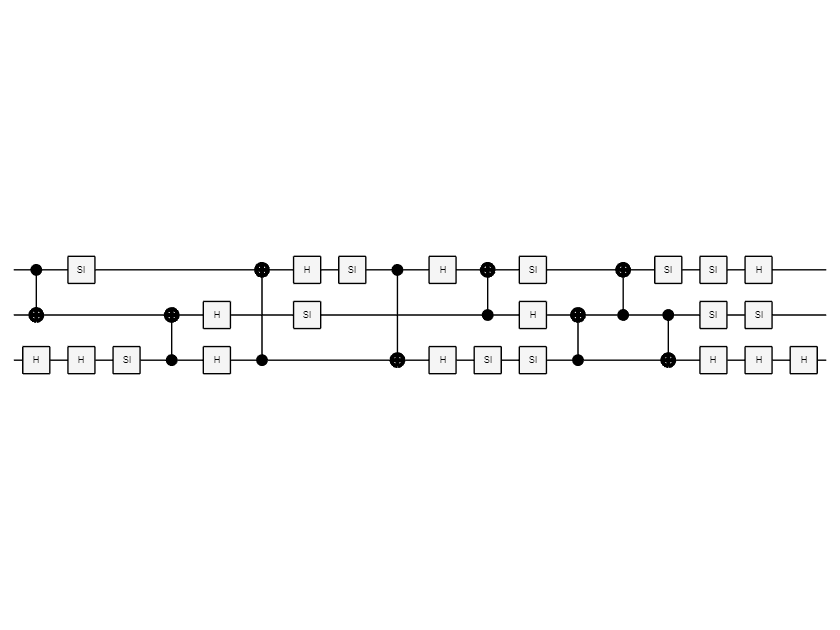

Error using dec2bin
D must be numeric.

cliffordDecrypt = DecryptedCircuit;
%ig = initGate(1:3, "101");
rev_swap_gates = reverseSwapGates(swap_gates);
gates = [cliffordDecrypt; rev_swap_gates;];
D = quantumCircuit(gates);

plot(D);

codeword = [];
while strlength(message)>= nQubits
    chunk = extractBefore(message, nQubits+1); % Extracts up to index n
    message = extractAfter(message, nQubits);    % Extracts from index n+1
    codeword = [codeword;chunk];
end
if strlength(message) > 0
    last_chunk = "";
    for i = 1:nQubits-strlength(message)
        last_chunk = "0" + last_chunk ;
    end
    last_chunk = message+last_chunk;
    codeword = [codeword;last_chunk];
end
disp(codeword)

states = [];
gates = [swap_gates;cliffordEncrypt;cliffordDecrypt;rev_swap_gates];
E = quantumCircuit(gates);
plot(E);
for i = 1:length(codeword)
    s = simulate(E,codeword(i));
    %disp(codeword(i));
    %s = simulate(C,codeword(i));
    disp(formula(s));
    %t = simulate(D,s);
    %disp("t");
    %disp(formula(t));
end




%%%Testing the reversing of the permutation%%%
% Define the initial codeword
codeword = ['D', 'O', 'G', 'S','C','H','I','L','L','I','N','!'];

% Define the permutation
p = randperm(length(codeword)); 
% Function to generate swap gates
swapList = permutationToSwapGates(p);
% Apply the swap gates sequentially
for i = 1:size(swapList, 1)
    codeword = applySwapGate(codeword, swapList(i).TargetQubits(1), swapList(i).TargetQubits(2));
end

% Display the final codeword
disp('Final codeword:');
disp(codeword);
%Undo the permutation
%inv = invert_permutation(p);
%swapList_inv = permutationToSwapGates(p);
% **Apply swaps in reverse order to undo the permutation**
for i = size(swapList, 1):-1:1
    codeword = applySwapGate(codeword, swapList(i).TargetQubits(1), swapList(i).TargetQubits(2));
end

disp('Recovered codeword:');
disp(codeword);
function reversedSwapGates = reverseSwapGates(swapList)
    reversedSwapGates = flipud(swapList);
end
% Function to simulate a swap gate for testing
function swappedWord = applySwapGate(codeword, i, j)
    swappedWord = codeword;
    temp = swappedWord(i);
    swappedWord(i) = swappedWord(j);
    swappedWord(j) = temp;
end
function permutationInverse = invert_permutation(p)
    n = length(p);
    %Create an array of the same size as the original permutation
    permutationInverse = zeros(1, n);
    %to invert a mapping of x to y we do y to x
    for y = 1:n
        x = p(y); %x is at position y
        permutationInverse(x) = y; %put y at position x
    end
end

function DecryptedClifford = decrypt_clifford(EncryptedClifford)
    % Reverse the gate order
    DecryptedClifford = flipud(EncryptedClifford);
    disp(DecryptedClifford)
    % Loop through each gate and modify it if needed
    for i = 1:length(DecryptedClifford)
        gate = DecryptedClifford(i); %Get the current gate
        if strcmp(gate.Type, "s")
            DecryptedClifford(i) = siGate(gate.TargetQubits);
        end
        % hGate and cxGate remain unchanged
    end
end

f

% function to turn a qubit permutation into a set of transpositions to fit
% it into the swapGate function
function swapList = permutationToSwapGates(p)
    n = length(p);
    visited = false(1, n);
    swapList = [];
    for i = 1:n
       if ~visited(i)
           cycle = [];
           j = i;
           while ~visited(j)
               visited(j) = true;
               cycle(end+1) = j;
               j = p(j);
           end
           if length(cycle) > 1
               for k = length(cycle):-1:2
                   newGate = swapGate(cycle(1), cycle(k));
                   swapList = [swapList; newGate];
               end
           end
       end
    end
end

Generate an array of X clifford operators by combining known clifford operators

function CliffordSet = generate_unique_cliffords(nQubits, d1)
   CliffordSet = cell(1, d1);
  
   for i = 1:d1
       qc = quantumCircuit(nQubits);
       newClifford = [];
       switch nQubits
           case 2
               gatecount = 1:randi([2, 3]);
           case 3
               gatecount = 1:randi([3, 50]);
           case 4
               gatecount = 1:randi([3, 10]);
           case 5
               gatecount = 1:randi([3, 200]);
           case 6
               gatecount = 1:randi([3, 300]);
       end
      
       % Generate random Clifford explicitly
       for gateIdx = gatecount
           gateType = randi(3);
           targetQubit = randi(nQubits);
           switch gateType
               case 1, g = hGate(targetQubit);
               case 2, g = sGate(targetQubit);
               case 3
                   control = randi(nQubits);
                   while control == targetQubit
                       control = randi(nQubits);
                   end
                   g = cxGate(control, targetQubit);
           end
           newClifford = [newClifford; g];
       end
       CliffordSet{i} = newClifford;
   end
end